FlightData = ardupilotreader("C:\Users\theon\OneDrive - Cal Poly Pomona\Documents\DUST-4\Flight_Test_Validation_files\00000028.BIN");

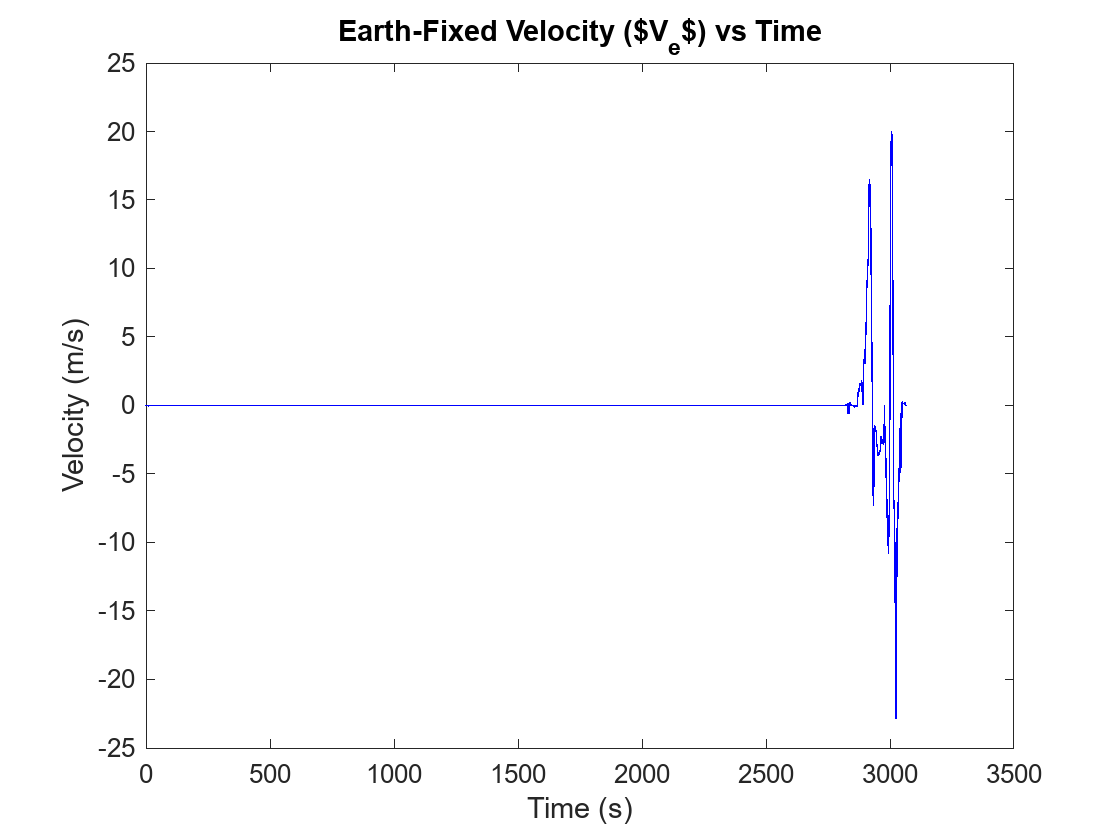

% 1. Read the ArduPilot binary log file
% --- TIME CALCULATION (Using Manual Division for compatibility) ---
% Extract RATE messages for the TimeUS field
AR = readMessages(FlightData,"MessageNames","XKF1"); 

% Convert TimeUS (microseconds) to seconds 
Time_sec_raw = seconds(AR.MsgData{1,1}.TimeUS);
Time_Column = (Time_sec_raw - Time_sec_raw(1))';
% Calculate the relative time (Time) in seconds, starting from t=0

% --- VELOCITY EXTRACTION AND CONVERSION ---

% 2. Extract the EKF3 XKF1 messages for Earth-fixed velocity in m/s


% Extract the North (VN), East (VE), and Down (VD) velocity components (m/s)
Ve_N_mps = EKF3.MsgData{1,1}.VN';
Ve_E_mps = EKF3.MsgData{1,1}.VE;
Ve_D_mps = EKF3.MsgData{1,1}.VD;

Ve_N_Simulink_Input = [Time_Column, Ve_N_mps];
% Define the conversion factor
%CONV_FACTOR = 3.28084; % 1 meter = 3.28084 feet

% 3. Convert all velocity components from m/s to ft/s
% Ve_N_ftps = Ve_N_mps * CONV_FACTOR;
% Ve_E_ftps = Ve_E_mps * CONV_FACTOR;
% Ve_D_ftps = Ve_D_mps * CONV_FACTOR;


% --- PLOTTING ---

figure; % Create a new figure window

% Plot North Velocity (VN) in blue
plot(Time_Column, Ve_N_mps, 'b');
title('Earth-Fixed Velocity ($V_e$) vs Time');
xlabel('Time (s)');
ylabel('Velocity (m/s)');

% % Hold the current plot to overlay the other rates
% hold on;

% % Plot East Velocity (VE) in red
% plot(Time, Ve_E_ftps, 'r');
% 
% % Plot Down Velocity (VD) in green
% plot(Time, Ve_D_ftps, 'g');
% 
% % Add a legend to identify the lines
% legend('North Velocity (V_N)', 'East Velocity (V_E)', 'Down Velocity (V_D)', 'Location', 'best');

% Ensure the hold state is released
hold off;

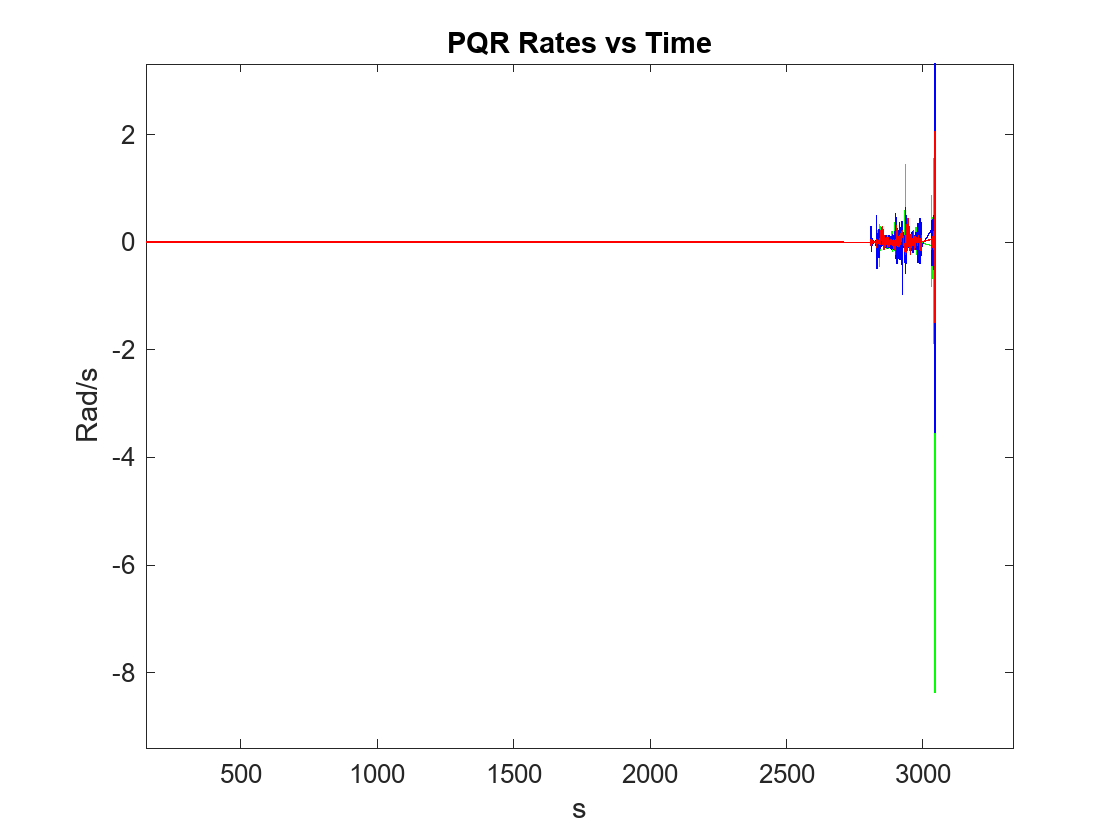

%Angular rates

AR = readMessages(FlightData,"MessageNames","RATE");
PRate_deg = AR.MsgData{1,1}.P;
PRate_rad = deg2rad(PRate_deg);
RRate_deg = AR.MsgData{1,1}.R;
RRate_rad = deg2rad(RRate_deg);
YRate_deg = AR.MsgData{1,1}.Y;
YRate_rad = deg2rad(YRate_deg);
% 
t_AR1 = seconds(AR.MsgData{1,1}.TimeUS - AR.MsgData{1,1}.TimeUS(1));
 Vbi = [1, 1, 1];
% 
TimeStamp = duration(AR.MsgData{1,1}.TimeUS(1:end)) - AR.MsgData{1,1}.TimeUS(1);
Time = seconds(TimeStamp); 
plot(Time,PRate_rad,'g')
title('PQR Rates vs Time');
xlabel('s');
ylabel('Rad/s');
hold on
plot(Time,RRate_rad,'b');
hold on
plot(Time,YRate_rad,'r');


%Sending these variables to Simulink
% p_ts = timeseries(RRate_rad, Time); %Roll Rate
% q_ts = timeseries(PRate_rad, Time); %Pitch Rate
% r_ts = timeseries(YRate_rad, Time); %Yaw Rate
% 

 %Body Velocity (Vb)
Vb_x = XKF1.MsgData{1,1}.VX';
Vb_y = XKF1.MsgData{1,1}.VY;
Vb_z = XKF1.MsgData{1,1}.VZ;

